# Raíces de una función

clear;
close all;
% Global settings
warning('off'); % warnings about rank

El siguiente ejercicio contiene los siguientes codigos para su desarrollo

- [bisection.m](matlab:open('./bisection.m'))

- [newtonraphson.m](matlab:open('./newtonraphson.m'))

## 3.1 Entendiendo las distintas metodologías

### 3.1.1 Newton-Rpahson

El algoritmo de Newton-Raphson permite encontrar la raíz de una función partiendo desde un punto del dominio cercano a dicha raíz. Es un método **iterativo** y preciso que es útil sobre polinomios de grado *impar*. Desde una aproximación de **Taylor** de primer orden es posible obtener la siguiente sucesión que define el algortimo. Es importante notar que  dos valores consecutivos de la sucesión serán cada vez más similares en la medida en que se aproximen a la raíz de la función :


$$x_{n+1} \;=x_n$$

$$=\frac{\;f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$
  

Con $x_o \;\textrm{conocido}\ldotp \;$La figura adjunta en el enunciado explica de forma gráfica el método de estudio

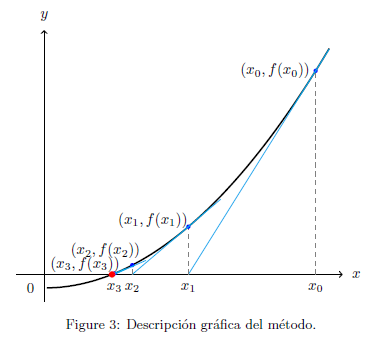

Formalmente sea  $f\left(x\right)$ una función $C^1$ y continua, y $x_r$ una raíz desconocida sobre $f\left(x\right)$. Asumamos que $x_o$ es un *guess para *$x_r$. A menos que hayamos tenido mucha suerte, $f\left(x_o \right)$ no es una raíz. Dado ese escenario queremos encontrar un $x_1$ tal que se mejore la performance de $x_o$ (esto es, estar más cerca de $x_r$ que de $x_o$). Ahora bien. si suponemos que de todas maneras $x_o$ esta lo suficientemente cerca de $x_r$ , entonces podremos hacer una **aproximación lineal de **$f\left(x\right)$ alrededor de $x_o$ tal que buscaremos encontrar la intersección de esa línea con el eje x. En síntesis, estaremos haciendo una aproximación lineal de $f\left(x\right)$ alrededor de $x_o$ que se escribe de la siguiente manera:


$$f\left(x\right)\approx f\left(x_o \right)+f^{\prime } \left(x_o \right)\;\left(x-x_o \right)$$
 

Luego, como indicamos, encontraremos $x_1$ tal que $f\left(x_1 \right)=0$. Tomando esos valores y llevándolos a la aproximación lineal resulta la siguiente ecuación:


$$\begin{array}{l}
0=f\left(x_o \right)+f^{\prime } \left(x_o \right)\;\left(x-x_o \right)\\
x_1 =x_0 -\frac{f\left(x_0 \right)}{f^{\prime } \left(x_o \right)}
\end{array}$$


En términos generales, el método** de Newton **computa la aplicación del guess, $x_n$, usando un guess anterior $x_{n-1}$ y que está dado por la siguiente ecuación


$$x_n =x_{n-1} =\frac{g\left(x_{n-1} \right)}{g^{\prime } \left(x_{n-1} \right)}$$


Ahora bien el método **Newton-Raphson **aplica encontrar esa raíz pero iterando el método de Newton desde $x_0 \;$ hasta que el error sea menor a una tolerancia esperada. 

### 3.1.2 Algoritmo de Bisección

Basado en el teorema de los Valores Intermedios, el algoritmo de Bisección establece: 

Sea$\begin{array}{l}
f:\left\lbrack a,b\right\rbrack \longrightarrow R\;\mathrm{una}\;\mathrm{función}\;\mathrm{continua}\;{\mathrm{diferenciable}\;C}^{1\;} \;\mathrm{donde}\;\mathrm{todo}\;\mathrm{valor}\;\mathrm{entre}\;f\left(a\right)\;\;y\;f\left(b\right)\;\mathrm{es}\;\mathrm{imagen}\;\mathrm{de}\;\mathrm{al}\;\mathrm{menos}\;\mathrm{un}\;\mathrm{valor}\;\mathrm{del}\;\mathrm{intervalo}\;\left\lbrack a,b\right\rbrack \ldotp \\
\mathrm{Luego},\mathrm{si}\;f\left(a\right)\;y\;\;f\left(b\right)\;\mathrm{tienen}\;\mathrm{signos}\;\mathrm{opuestos}\;\left(f\left(a\right)\cdot f\left(b\right)<0\right),\mathrm{el}\;\mathrm{teorema}\;\mathrm{asegura}\;\mathrm{la}\;\mathrm{existencia}\;\mathrm{de}\;\mathrm{al}\;\mathrm{menos}\;\mathrm{un}\;\mathrm{valor}\;x\;\mathrm{del}\;\mathrm{dominio}\;\mathrm{de}\;\mathrm{la}\;\mathrm{función}\;\mathrm{que}\;\mathrm{cumple}\;f\left(x\right)=0\;
\end{array}$

Para programar el algoritmo de Bisección siga los siguientes pasos

- Compute una tolerancia $\tau =10{\;}^{-4}$ y defina un intervalo [a,b] que contenga la raíz de la función.

- Dada una función que cumpla con las características, compute f(a) y f(b)

- Compute $\bar{r} =\frac{a+b}{2}$ y luego obtenga $f\left(\bar{r} \right)$. Si el signo de  $f\left(\bar{r} \right)$ es igual al signo  $f\left(a\right)$, entonces el nuevo intervalo definido en el dominio de la función seá  $\left\lbrack \bar{\;r} ,b\;\right\rbrack \;\textrm{de}\;\textrm{otra}\;\textrm{forma}\;\textrm{el}\;\textrm{nuevo}\;\textrm{intervalo}\;\textrm{será}\;\left\lbrack a,\bar{\;r} \right\rbrack \ldotp$

- Compute el error de aproximación  $\epsilon =f\left(\bar{\;r} \right)$

- Mientras  $\epsilon >\tau \;$ repita el proceso hasta que el algoritmo converja a la tolerancia deseada

Generalmente el algoritmo de bisección no produce una solución exacta a la ecuación f(x)=0. Ahora bien, se puede proveer de una estimación sobre el error absoluto. El teorema es el siguiente.

Teorema. Sea f(x) una función continua entre [a,b] tal que f(a)f(b) < 0. Luego de N iteraciones del método de bisección, sea $\left\lbrack X_n \right\rbrack$ el punto intermedio en el subintervalo n-ésimo $\left\lbrack a_n ,b_n \right\rbrack$


$$X_n =\frac{a_n +b_n }{2}$$


Entonces, existe una solución exacta y verdadera de la ecuación $f\left(x\right)=0$ en el subintervalo $\left\lbrack a_n ,b_n \right\rbrack$ y el error absoluto es


$$\epsilon >\left\lbrack x*-x_n \right\rbrack \le \frac{b-a}{2^{\;n+1} }$$


Notemos que podemos reorganizar el límite del error de modo de poder notificar cuál es el número mínimo de iteraciones requeridas para garantizar que el error absoluto sea menor al descrito


$$\begin{array}{l}
\frac{b-a}{2^{\;n+1} }<\epsilon \\
\frac{b-a}{\epsilon }<2^{\;n+1} \\
\ln \frac{b-a}{\epsilon }<n+1\cdot \ln \left(2\right)\\
\frac{\ln \frac{b-a}{\epsilon }}{\ln \left(2\right)}\;-\;1<n
\end{array}$$


(a) Usando el método Newton-Raphson, encuentra la raiz de las siguientes funciones

 
$$\begin{array}{l}
f\left(x\right)=x^{3\;} +x+2\\
f\left(x\right)=x^{5\;} +x^4 +x^3 +x^2 +1\\
f\left(x\right)=\log \left(x\right)+\log \left(3x^3 \right)
\end{array}$$
 

clear;
f = @(x) x^3 -x + 2;
x0= 0

x0 = 0

newtonraphson(f,x0)

ans = -1.5214

x0 = 1;
F = {@(x) x.^3-x+2; @(x) x.^5+x.^4+x.^3+x.^2+1; @(x) log(x)+log(3*x.^3)} ;
newtonraphson(F{1},x0)

ans = -1.5214

newtonraphson(F{2},x0)

ans = -1.2499

newtonraphson(F{3},x0)

ans = 0.7598

(b) Obtenga la raíz de las funciones usando el algoritmo de Bisección. ¿Obtiene los mismos resultados?

Como podemos ver se obtienen los mismos resultados para ambos métodos numéricos de cálculo de raíces

% La funcion bisection calcula para un f e intervalo a,b, la raiz y error
F = {@(x) x.^3-x+2; @(x) x.^5+x.^4+x.^3+x.^2+1; @(x) log(x)+log(3*x.^3)} ;
a = -6;
b = 6;
bisection(F{1},a,b)

Solucion: -1.5214  Error: 2.6274e-46


ans = -1.5214

bisection(F{2},a,b)

Solucion: -1.2499  Error: 8.7581e-47


ans = -1.2499


% Para log definimosel intervalo entre 0 y +infinito pues en negativos se
% indefine y ya no se cumpliría el teorema
bisection(F{3},0,12)

Solucion: 0.75984  Error: 2.1895e-47


ans = 0.7598

(c) ¿Cuál algoritmo es más eficiente? Justifique brevemente

f = @() bisection(F{1},a,b); % handle to function
timeit(f) 

Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46
Solucion: -1.5214  Error: 2.6274e-46


ans = 2.5035e-04

f = @() newtonraphson(F{1},x0); % handle to function
timeit(f)

ans = 0.0217

Si medimos la eficiencia en términos de tiempo en que se demora el método en calcular la raíz,  el algoritmo de bisección se demora 0.0048 segundos, mientras que el algoritmo de Newton Raphson se demora 0.0270segundos. Ahora bien, en programación la eficiencia no solo tiene que ver con el tiempo si no que de los parámetros con los cuales se construyen las funciones, y su capacidad de replicabilidad. Por ello, presentaré una breve discusión de las ventajas y desventajas de ambos métodos, haciendo alusión a sus potencales respecto a eficiencia y eficacia (precisión). 

- La ventaja principal del método de Newton es que cuando se converge, esto ocurre rápidamente. Ahora bien, no asegura la existencia de esa convergencia, lo que evidentemente es una desventaja comparada con el método de bisección que garantizan la convergencia hacia una solución. 

- Además, el método de Newton requiere computar las derivadas de la función objetivo, algo que potencialmente puede ser una desventaja si la derivada es difícil de calcular. 

- Penúltimo el criterio de convergencia del método de Bisección y Newton es muy distinto: en el primero nosotros sabemos qué tan cerca estamos de la solución pues estamos computando la estimación dentro de intervalos que si o si contienen la solución; en el segundo, no sabemos realmente que tan cerca estamos de la solución. 

- Por último, computacionalmente es mucho menos preciso Newton que Bisección. Esto pues en el primero debemos indicar hasta que número de iteraciones se quiere seguir probando la convergencia, mientras que en método de bisección el criterio de *stopping *es qué tan pequeño es el error de estimación. Las iteraciones quedan sujetas a ello. 

(d) Cree las funciones NR y BS que permite encontrar las raíces de una función con características indicadas mediante el método Newton-Raphson y Bisección respectivamente. Utilice las funciones para computar raíces de los incisos anteriores nuevamente. 

Las funciones se crearon enseguida, dado que me es más fácil pensar en las funciones en términos generales y luego ver si su aplicación funciona para los casos particulares propuestos. 

Solo agregar que en ambos métodos de igual manera debe existir una vigilancia del usuario sobre los **dominios de la función**. No es trivial dónde viven las funciones a evaluar, por lo que son métodos dependientes de las cotas de las funciones. Por lo mismo se crearon *warnings *ante ciertas propiedades que el usuario no podría preveer. Por ejemplo, 

- El número de iteraciones excede las que el programa se propuso. Para lograr converger se propusieron al menos 100 para Newton-Raphson, mientras que para Bisección eso no fue necesario. 

- En el caso de bisección la direccionalidad de las funciones era relevante, por lo que dado el teorema, era necesario asegurarse que las soluciones de la función vivieran dentro del intervalo. Lo positivo es que da igual si se elige un intervalo mayor al encontrado (por ejemplo que la solución viva entre [a,b] pero se elija [a+30,b+30]) pues la estimación es tan consistente que eso no trae probelmas. 

### 3.2 Aplicación de tiro vertical

En física la noticación de Tiro Vertical describe un movimiento rectilíneo uniformemente acelerado, es decir, un movimiento que se caracteriza por tener aceleración constante. Este tipo de movimiento intenta estudiar la trayectoria de objetos que son lanzados verticalmente desde una cota inferior hacia una cota superior, es decir, hacia arriba. Una buena forma de comprender este movimiento es imaginar a una maquina “lanzapelotas” posicionada en 90°. La trayectoria del movimiento de la pelota puede ser explicada por las ecuaciones de un Tiro Vertical.

El propósito de este ejercicio es utilizar el algoritmo de Bisecció y Newton-Raphson para hallar la solución al problema.

Contexto

Imagine que durante un día de partido de tenis, su rival no se presenta y usted decide practicar su saque con la ayuda de una máquina “lanzapelotas”. Para optimizar sus movimientos y energía, **desea saber el momento exacto en que la pelota alcanzar a la altura máxima en su recorrido**, de tal forma de poder aplicar un golpe limpio. Usted sabe que las ecuaciones de Tiro Vertical son las que mejor describen el movimiento de la pelota y están dadas por


$$h\left(t\right)=h_o +v_o \cdot t-\frac{1}{2}g\cdot t^{2\;}$$



$$\begin{array}{l}
h\left(t\right):\mathrm{altura}\;\mathrm{de}\;\mathrm{la}\;\mathrm{pelota}\;\mathrm{al}\;\mathrm{instante}\;t\\
h_o :\mathrm{altura}\;\mathrm{inicial}\to 50\;\left(\mathrm{cm}\right)\\
v_o :\mathrm{velocidad}\;\mathrm{incial}\to 4\ldotp 5\;\left(\frac{m}{s}\right)\\
g:\mathrm{aceleración}\;\mathrm{de}\;\mathrm{gravedad}\to 9\ldotp 81\;\left(\frac{m}{s^2 }\right)
\end{array}$$


(a) Mediante el algoritmo de Bisección y Newton-Raphson obtenga el tiempo $t^*$ en el cual la pelota alcanza la altura máxima.

El lanzamiento de la pelota es una parábola cuya trayectoria se describe por h(t). En ese sentido nosotros queremos saber cuál es la cúspide de esa trayectoria, o mantemáticamente, queremos saber el valor de  $t\;\mathrm{cuando}\;\frac{\partial \;h\left(t\right)}{\partial \;t}=0$. Los pasos son 

- Encontrar y clasificar los extremos globales de la funcion (que realizaremos con método Newton-Raphson y Biseccion)

- Encontrar los puntos críticos computando la primera derivada y luego despejando t

f = @(t)50+4.5*t -0.5*9.81*t^2; % Expresamos el problema numericamente y con x=t

Si calculamos con el método de Newton Raphson obteneremos la menor raíz de la solución (t = *-2.7668*)

t0= 0 % guess

t0 = 0

newtonraphson(f,t0)

ans = -2.7668

Cuando calculamos con el método de bisección obtenemos la mayor raiz de la solución (t=*3.6843*)

bisection(f,0,8)

Solucion: 3.6843  Error: 8.7581e-47


ans = 3.6843

Hasta aquí uno se podría asustar y pensar que hay un error. Pero, recordemos lo que indicamos al inicio de este ejercicio: ambos métodos son eficientes pero sensibles a los intervalos por el cuál nosotros los estudiamos, por lo que podremos muchas veces obtener raíces para máximo o mínimos, y no necesariamente serán los globales. Veamos si tomamos el método de bisección por el otro lado obtenemos la raíz *-2.7668*

bisection(f,-8,0)

Solucion: -2.7668  Error: 1.7516e-46


ans = -2.7668

Lo mismo con Newton Raphson

newtonraphson(f,1)

ans = 3.6843

Lo que evidentemente evidencia es que **entre estas raíces existe el máximo de la función, y con ello podemos clasificar los extremos globales de la función**

El segundo paso que viene consiste en derivar la función

syms t
f1 = str2sym(char(f));
df = diff(f1);
df = matlabFunction(df);
% Obtener punto critico. Sabemos que newton raphson funcional igual, asi
% que para simplificar ocupamos biseccion
[t1] = bisection(df,0,8)

Solucion: 0.45872  Error: 2.1895e-47


t1 = 0.4587

Entonces con la primera bisección encontramos los intervalos donde vive el máximo o mínimo global, y ahora con la segunda de estas obtuvimos el máximo.

(b) Obtenga la altura máxima que alcanza la pelota.

Tenemos que evaluar la función original y obtentemos el maximo

maxf =  50+4.5*t1 -0.5*9.81*t1^2; 

Nuevamente, como nuestro punto crítico vive en el intervalo de los zeros que calculamos inicialmente podemos decir que en 0.4591 " es un punto de inflexión entre mínimos globales y máximos globales.

(c) ¿Cuál es la velocidad de la pelota en el instante t? ¿Por qué son válidos estos algoritmos para encontrar la solución al problema? Explique brevemente

La velocidad se obtiene así


$$v\left(t\right)=\frac{\partial h\left(t\right)}{\partial \;t}=-9\ldotp 8t+4\ldotp 5$$
 

 -9.8*t1 + 4.5

ans = 0.0046

Notemos que la velocidad en ese punto es aproximadamente cero, lo que rectifica que nuestros cálculos son correctos dado que en un movimiento parabólico regido por MRU y MRUA, cuando se alcanza el máximo de distancia, el vector velocidad es igual a cero debido a que el cuerpo pierde toda su energía cinética que lo hizo desplazarse hacia la posición máxima. Luego, el cuerpo va a seguir su trayectoria pero a una velocidad dependiente de la aceleración. Formalmente cuando la velocidad en el eje y vale 0, obtenemos el tiempo t que tarda el cuerpo en llegar a dicha altura.

Ahora respecto a la validez de estos métodos para estos problemas, se pueden hacer dos acotaciones, una formal y otra sustantiva. 

- El movimiento descrito consiste en una función f: $R^2 \to R$ , acotada, continua y diferenciable en todo su intervalo. En ese sentido tanto el método de Newton como de Bisección que se inspira en el **teorema del valor intermedio**, pueden ser matemáticamente aplicados. 

- En términos sustantivos, nosotros tenemos una trayectoria que se describe por una función de la cuál desconocemos sus puntos o raíces exactamente. Una forma de aproximarnos es partir conociendo sus valores extremos (Teorema de Weierstrass). Una vez conocido ese máximo y ese mínimo, por el teorema de la acotación (Bolzano) podemos establecer que en toda función continua cerrada, esta es acotada. El ejercicio será ir construyendo cada vez menores intervalos que nos lleven a un único valor c que está contenido en la cota. Gráficamente

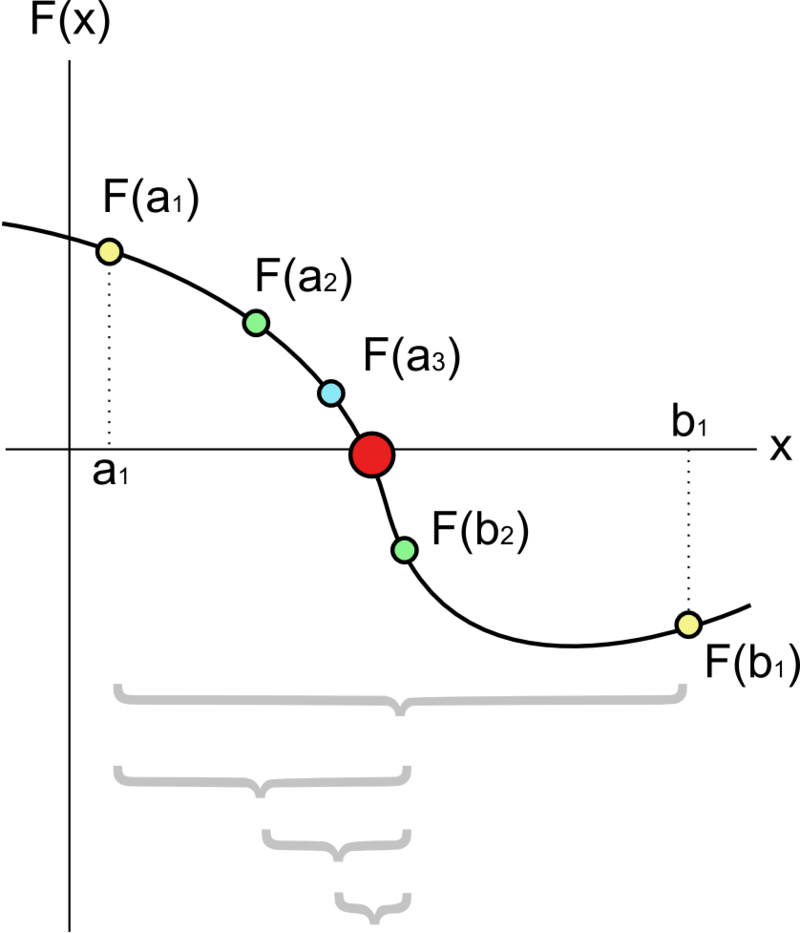

En ese sentido, en esta búsqueda por ese f(c) = 0,  estaremos **mapeando** todo el recorrido de la función. Con esa aproximación, luego, podemos conocer cualquier momento de nuestra distribución, tal como los puntos máximos, la velocidad (varianza) u otros.

(d) Imagine que ahora desea estudiar el movimiento denominado caída libre, ¿Podría utilizar las funciones NR y BS para estudiar la trayectoria del objeto de estudio? No es necesario que haga cálculos. Explique brevemente la lógica que hay detrás de los movimientos estudiados.

Anteriormente se entregó una intuición sobre el estudio de funciones de las cuales tenemos información general, pero no sabemos cómo se comporta en cada uno de los puntos. Un punto de partida es el teorema de los valores extremos absolutos, para luego pasar al teorema de la acotación, ambos componentes esenciales del teorema del valor intermedio (de hecho, este es un resultado de estos). Una vez reconocido eso entendremos que **si se puede tomar otro movimiento que se comporta como una subsucesión de cada punto de la sucesión general (la función del movimiento parabólico), entonces podremos también aplicar esta metodología. **

En términos simples, la caída libre que va en la misma dirección que el proyectil en la parábola se comporta de igual manera que un movimiento parabólico, solo que comprende la trayectoria desde que la altura es máxima (y velocidad cero), hasta cuando el proyectil toca el piso. En condiciones ideales donde estos proyectiles son lanzados al aire (y no hay resistencia) podemos notar que 

- La caída libre y el lanzamiento del proyectil desde una misma altura tardan lo mismo en llegar al suelo

- Tanto en esta parábola como semiparábola, la masa es independiente de la trayectoria. 

Como resultante la función que describe el tiempo que tarda en llegar a la altura máxima el cuerpo, es el mismo que tarda en llegar desde el punto máximo hacua el suelo, y por consiguiente, incluso basta con calcular una semiparábola de caída libre y obtendremos el mismo resultado respecto a los momentos de la función. La única diferencia es **el intervalo de análisis, algo que recalcamos bastante al inicio. **Así, en el caso de la parábola tomamos todo el intervalo comprendido entre sus raíces, mientras que en la semiparábola, la cota inferior corresponderá a la altura dada del problema (que debe coincidir con la máxima de la parábola completa). 

En síntesis, si la caída libre sigue la misma trayectoria de lanzamiento que el movimiento parabólico, podemos llegar a los mismo resultados. Cosa distinta es si la caída libre es totalmente independiente, pues en ese caso, tendremos que evaluar la función objetivo nuevamente con la misma rigurosidad con que lo hicimos para el caso del movimiento parabólico. 

### Apéndice

1.Resolvamos x en los números reales


$$\begin{array}{l}
-4\ldotp 9x{\;}^2 +4\ldotp 5x+50=0\\
x^2 -\frac{45}{49}x-\frac{500}{49}=0\\
{\left(x-\frac{45}{98}\right)}^2 =\frac{100025}{9604}
\end{array}$$


2. Tomemos el cuadrado por ambos lados


$${x_1 }^{*\;} =\frac{45}{98}+\frac{5\;\sqrt[]{4001}}{98}\;\approx 3\ldotp 6843\;\;\;\;\;\;\;\;\;\;\;{x_2 }^{*\;} =\frac{45}{98}-\frac{5\;\sqrt[]{4001}}{98}\;\;\;\;\approx -2\ldotp 7668\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$
